# Implement Incremental Learning for Classification Using Flexible Workflow

## Load and Preprocess Data

clc, clear, close all
load humanactivity
rng(1) % For reproducibility
n = numel(actid); % 24075
idx = randsample(n, n); % shuffle, sampled uniformly, without replacement
X = feat(idx, :)'; % 60-by-24075
Y = actid(idx);    % 24075-by-1 logical

Y = Y > 2;

## Train Linear Model for Binary Classification

idxtt = randsample([true false], n, true); % 1-by-24075 logical, resample with replacement, either 0 or 1
TTMdl = fitclinear(X(:,idxtt), Y(idxtt), 'ObservationsIn', 'columns') % fit model using all data, specify predictor data observation dimension

TTMdl =   ClassificationLinear
      ResponseName: 'Y'
        ClassNames: [0 1]
    ScoreTransform: 'none'
              Beta: [60×1 double]
              Bias: -0.3005
            Lambda: 8.2967e-05
           Learner: 'svm'


  Properties, Methods


## Convert Trained Model

 IncrementalMdl = incrementalLearner(TTMdl)

IncrementalMdl =   incrementalClassificationLinear

            IsWarm: 1
           Metrics: [1×2 table]
        ClassNames: [0 1]
    ScoreTransform: 'none'
              Beta: [60×1 double]
              Bias: -0.3005
           Learner: 'svm'


  Properties, Methods


## Implement Incremental Learning

% Preallocation
idxil = ~idxtt; 
nil = sum(idxil); % 12022
numObsPerChunk = 50; % the number of observations in single chunk of data
nchunk = floor(nil/numObsPerChunk); % 240, the number of the chunks 
ce = array2table(zeros(nchunk,2),'VariableNames',["Cumulative" "Window"]);% 240-by-2 table, to record metrics
beta1 = [IncrementalMdl.Beta(end); zeros(nchunk,1)]; % record the initial and subsequent values of the last coefficient of 60, which is the number of predictors
Xil = X(:,idxil);  % 60-by-12022
Yil = Y(idxil);    % 12022-by-1

% Incremental fitting
for j = 1:nchunk
    % (1) Select chunk of data
    ibegin = min(nil, numObsPerChunk*(j-1) + 1);
    iend   = min(nil, numObsPerChunk*j);
    idx = ibegin:iend;
    
    % (2) Update performance metrics of the model given a new chunk of data using 'updateMetrics'
    IncrementalMdl = updateMetrics(IncrementalMdl, Xil(:,idx), Yil(idx), 'ObservationsIn', 'columns');
    ce{j,:} = IncrementalMdl.Metrics{"ClassificationError", :};

    % (3) Fit the model to the data using 'fit'
    IncrementalMdl = fit(IncrementalMdl, Xil(:,idx), Yil(idx), 'ObservationsIn', 'columns');
    beta1(j + 1) = IncrementalMdl.Beta(end); 
end

## Inspect Model Evolution

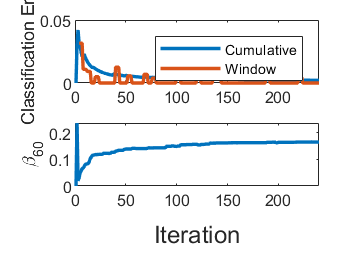

figure
% Create a tiled chart layout for displaying multiple plots in the current figure \beta_60
t = tiledlayout(2,1);
LineWidth = 1.7;

% Cumulative and window error
nexttile
h = plot(ce.Variables, LineWidth=LineWidth);
xlim([0 nchunk])
ylabel('Classification Error')
legend(h, ce.Properties.VariableNames)

% Estimated coefficient
nexttile
plot(beta1, LineWidth=LineWidth)
ylabel('\beta_{60}')
xlim([0 nchunk])
xlabel(t, 'Iteration')

*Copyright 2020 The MathWorks, Inc.*